obslat = 38.2590;
obslon = 15.5956;
obsH = 3397.00;

figure
geoaxes("Basemap","satellite","ZoomLevel",15)

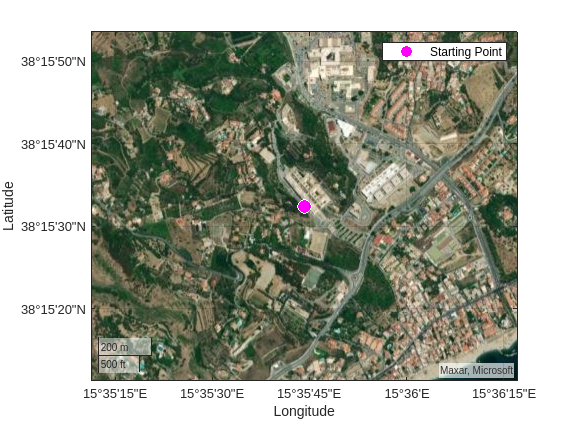

hold on
geoplot(obslat,obslon,"ow","MarkerSize",10,"MarkerFaceColor","magenta", ...
    "DisplayName","Starting Point")
legend

figpos = [1000 500 800 400];
uif = uifigure("Position",figpos);
ug = uigridlayout(uif,[1,2]);
p1 = uipanel(ug);
p2 = uipanel(ug);
gx = geoaxes(p1,"Basemap","satellite"); 
gg = geoglobe(p2); 
gx.InnerPosition = gx.OuterPosition;
gg.Position = [0 0 1 1];
heightAboveTerrain = 200;
gx.MapCenter = [obslat, obslon];
zoomLevel = heightToZoomLevel(heightAboveTerrain, obslat);
gx.ZoomLevel = zoomLevel;

N = egm96geoid(obslat, obslon);
obsh = obsH + N;
ellipsoidalHeight = obsh + heightAboveTerrain;
campos(gg,obslat,obslon,ellipsoidalHeight)
drawnow


T = readtable("subsampled.csv");
tlat= T.lat';
tlon = T.lon';
talt = T.alt';


wgs84 = wgs84Ellipsoid;
theading = azimuth(tlat(1:end-1),tlon(1:end-1),tlat(2:end),tlon(2:end),wgs84);
theading = [theading(1);theading(:)];


N = egm96geoid(tlat,tlon);
h = talt + N;


lat1 = tlat(1:end-1);
lat2 = tlat(2:end);
lon1 = tlon(1:end-1);
lon2 = tlon(2:end);
h1 = h(1:end-1);
h2 = h(2:end);
[dx,dy,dz] = ecefOffset(wgs84,lat1,lon1,h1,lat2,lon2,h2);



distanceIncrementIn3D = hypot(hypot(dx, dy), dz);


cumulativeDistanceIn3D = cumsum(distanceIncrementIn3D);
totalDistanceIn3D = sum(distanceIncrementIn3D);
fprintf("Total UAV track distance is %f meters.\n",totalDistanceIn3D)

Total UAV track distance is 11320.186934 meters.




tdist = [0 cumulativeDistanceIn3D];


geoplot3(gg,tlat,tlon,talt,"c","LineWidth",2,"HeightReference","geoid")
ptrack = geoplot(gx,tlat,tlon,"c","LineWidth",2);
[clat,clon,cheight] = campos(gg);
gx.MapCenter = [clat,clon];
gx.ZoomLevel = heightToZoomLevel(cheight, clat);
drawnow





campos(gg,tlat(1),tlon(1))
camheight(gg,talt(1) + 75)
campitch(gg,-90)
camheading(gg,theading(3))

hold(gx,"on")
marker = geoplot(gx,tlat(1),tlon(1),"ow","MarkerSize",10,"MarkerFaceColor","k");
mstart = geoplot(gx,tlat(1),tlon(1),"ow","MarkerSize",10,"MarkerFaceColor","magenta");
mend = geoplot(gx,tlat(end),tlon(end),"ow","MarkerSize",10,"MarkerFaceColor","blue");

marker.DisplayName = "Current Location";
mstart.DisplayName = "Start Location";
mend.DisplayName = "End Location";
ptrack.DisplayName = "UAV Track";
legend(gx)

gx.Basemap = "topographic";

dt = datatip(ptrack,"DataIndex",1,"Location","southeast");
dtrow = dataTipTextRow("Distance",tdist);
dtrow(end+1) = dataTipTextRow("Altitude",talt);
dtrow(end+1) = dataTipTextRow("Heading",theading);
ptrack.DataTipTemplate.DataTipRows(end+1:end+3) = dtrow;



pitch = -2.7689;
campitch(gg,pitch)

for k = 2:(length(tlat)-1)

    campos(gg,tlat(k),tlon(k))
    camheight(gg,talt(k)+100)
    camheading(gg,theading(k))
    
    set(marker,"LatitudeData",tlat(k),"LongitudeData",tlon(k));
    dt.DataIndex = k;
    
    drawnow
    pause(.05)
end

campos(gg,tlat(end),tlon(end),talt(end)+100)
dt.DataIndex = length(tlat);

function zoomLevel = heightToZoomLevel(height, lat)
    earthCircumference = 2 * pi * 6378137;
    zoomLevel = log2((earthCircumference *cosd(lat)) / height) + 1;
    zoomLevel = max(0, zoomLevel);
    zoomLevel = min(19, zoomLevel);
end